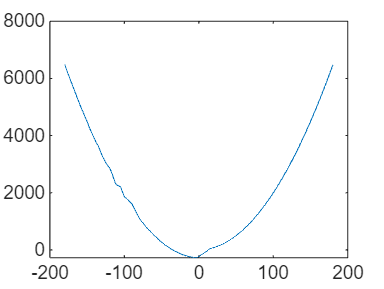

clc
clear 
rng(2024)


% 按照设定相位生成初始卫星队列
sat_num=19;
for k = 1:sat_num
    sat_index(1,k) = 0 + (k-1)*15; % initial phase index
end
sat_array=gen_satellite_array_by_index(sat_index);
A=gen_matrix_A(sat_array);
sat_group=gen_sat_group(sat_array);

h=1;
days=1;
for i=1:sat_num
    sat_array{i}=sat_array{i}.set_time_parameters(days,h);
    sat_array{i}=sat_array{i}.update();
end
% % 取出一组邻近卫星索引,
% opt_group=sat_group(1,:);
% index=1:1:sat_num;
% index=index(opt_group~=0);



% 
% sat_array{flag}=sat_array{flag}.set_orbit_parameters(-20);
% sat_array{flag}=sat_array{flag}.update();

gama=0.2;
fun=@(x)cal_ob_fun(x,sat_array,1,gama);
x=linspace(-180,180,1000);
for i=1:length(x)
    a(i)=fun(x(i));
end
plot(x,a)












% phi=linspace(-180,180,1000);
% for i=1:length(phi)
%     a=Satellite(phi(i));
%     a=a.set_time_parameters(1,1);
%     a=a.update();
% 
%     tau(1,i)=sum(a.tau)*(a.h/a.days);
% end
% tau=sum(tau)*(a.h/a.days)
% plot(phi,tau)
% a=Satellite(-20);
% sum(a.tau)*(a.h/a.days)
% 
% 360/15






% % 随机分布19个卫星在默认轨道
% 
% sat_num=19;
% sat_array=gen_satellite_array(sat_num);
% A=gen_matrix_A(sat_array);
% sat_group=gen_sat_group(sat_array);





